# Tutorial on Zernike polynomial calculations (Psych 221)

This tutorial is simplified. The extended version is in **ISETBIO**.

## About the Zernike polynomials

Zernike polynomials consist of: 

- a weighting coefficient (Zernike coeff), 

- a normalization factor

- a radially-dependent polynomial, and

- an azimuthally-dependent sinusoid

For example, one such polynomial (known as Astigmatism along 45 degrees) is given by:

where rho and theta are natural polar coordinates representing radial norm and angle on a disk. These can be easily converted to rectangular coordinates, making the Zernike polynomial representation useful for computing the wavefront aberrations.

Zernike polynomials can be expressed (referenced) using two indices, one representing the highest order of the radial polynomial term (n), and the other representing the frequency of the azimuthal sinusoid (m). (See wiki for more details.)

The polynomials can also be represented in a single-indexing scheme (j) using OSA standards, which is easier to manage in vector form for Matlab, so we will use it here.

Each radial order has (order+1) number of polynomial terms (and therefore, order+1 number of Zernike coefficients to represent them). Thus, 0th order has 1 term, 1st order has 2 terms, etc.

In this tutorial we will be working with up to 10 orders of Zernike polynomials. Counted out, this represents 1+2+3+...+11 = 66 terms for radial orders 0 through 10. The 0th order term (piston) doesn't affect the PSF and we will leave it at 0. Additionally, the 1st order terms (coeffs 1 and 2, known as tip and tilt) only serve to shift the PSF along the x or y axis. They will also be left at 0 for this tutorial.

(c) Wavefront Toolbox Team 2011, 2012

ieInit;

The tutorial only uses 1 wavelength at a time. So, for plotting, we use this index.

waveIdx = 1;
maxMM = 2;
maxUM = 20;      
pupilfuncrangeMM = 5;

## Use Zernike polynomials to specify a diffraction limited PSF.

#### Use wvfCreate to create a wavefront variable to explore with.

This wavefront by default has the 0's for all zernike coeffs. Notice that the calcpupilMM is by default 3, meaning we are simulating the wavefront PSF for a pupil of 3MM diameter.  This code dumps out the structure so you can get a sense of what is in it.

The validation script v_wvfDiffractionPSF compares the diffraction limited PSFs obtained in this manner with those obtained by computing an Airy disk and shows that they match.

wvf0 = wvfCreate;

Pupil diameter in mm.  This will change to meters some day


wvfPrint(wvf0);


Wavefront structure name is default

Zernike coefficients
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
	 Coeffs 0.000
Spatial sampling conditions
	Sampling constant across wavelength in "pupil" domain
	Number of spatial samples (pixels) for pupil function/psf: 201
	Size of sampled pupil plane (mm) at measurement wavelength: 16.212
	Pupil plane sampling interval (mm/pixel) at measurement wavelength: 0.0806567
Calculation parameters
	Pupil size (mm): 3
	Wavelengths:  400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700


#### Look at the plot of the normalized PSF within 1 mm of the center. 

Variable maxUM is used to specify size of plot from center of the PSF.

The plot shows an airy disk computed from the Zernike polynomials; that is representing the diffraction-limited PSF obtained when the Zernike coefficients are all zero.

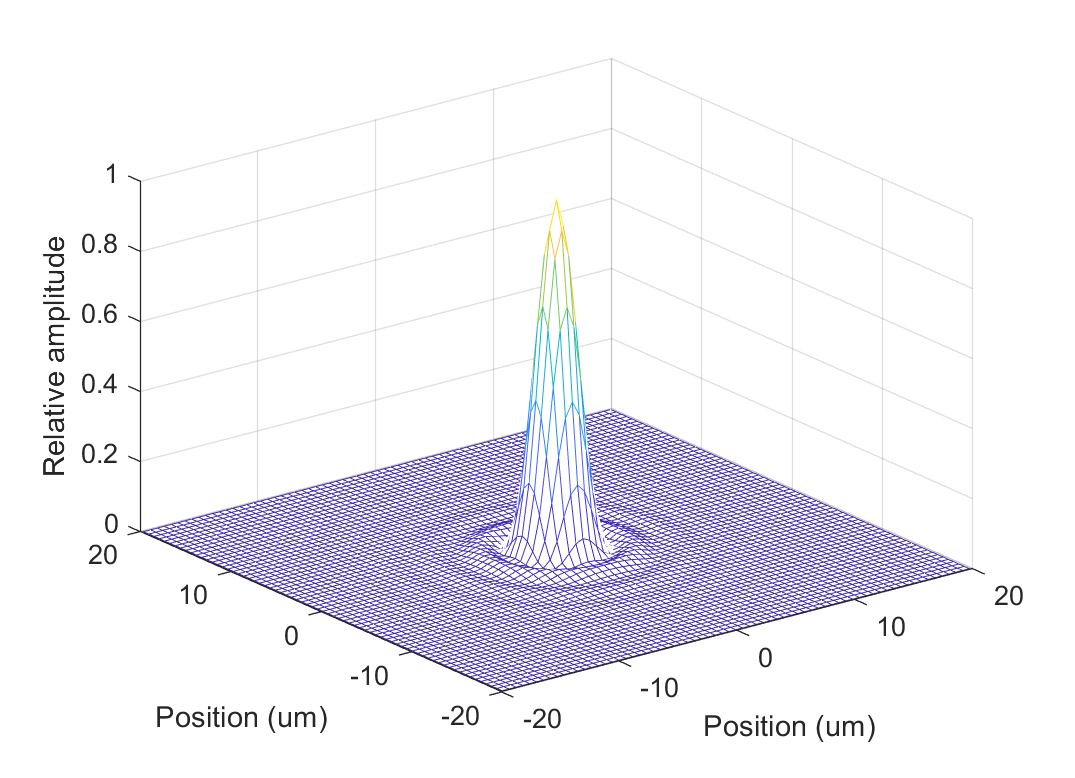

wvf0 = wvfComputePSF(wvf0);
% wList = wvfGet(wvf0,'wave');
wList = 550;
wvfPlot(wvf0,'2dpsf space normalized','um',wList,maxUM);

## Examine how the first non-zero Zernike coefficient contributes to the PSF.

The j = 3 coefficient (4th entry in the Zernike vector is known as oblique astigmatism (with axis at 45 degrees.)

We start with the default structure , wvf0 created above, which has its vector of zcoeffs set to 66 zeros.  Then we use wvfSet to poke in some non-zero oblique astigmatism.

Note that for low order coefficents with names, we wvfSet understands the names.  See wvfOSAIndexToVectorIndex for a list of available names.

We could also just specify 3 to the set function, as that is the corresponding OSA index.  This direct usage is illustrated by the wvfGet call, and the same usage works for the wvfSet.

(You can also get via names for the low order terms.)

oblique_astig = 2;                             
wvf3 = wvfSet(wvf0,'zcoeffs',oblique_astig,{'oblique_astigmatism'});
fprintf('Third Zernike coefficient is %g\n',wvfGet(wvf3,'zcoeffs',3));

Third Zernike coefficient is 2


## Look at the pupil function for astigmatism with axis at 45 degrees.

We have used wvfComputePupilFunction separately here, but it is actually also contained within wvfComputePSF, which we will use from now on.

We can see that the phase changes seem to be aligned with the + and - 45 degree axes, which makes sense for oblique astigmatism.

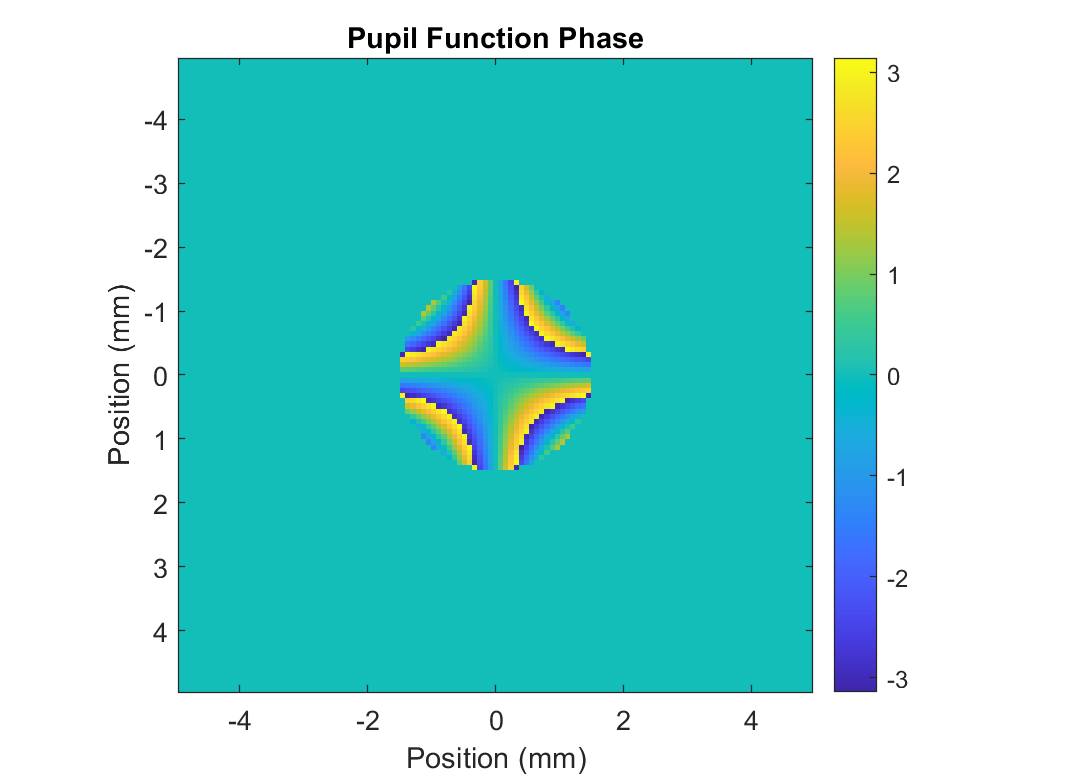

wvf3 = wvfComputePupilFunction(wvf3);
wvfPlot(wvf3,'2d pupil phase space','mm',wList,pupilfuncrangeMM);

## Plot the PSF

While the pupil functions are well specified by Zernike polynomials, it's hard to get meaning from them. We'd much prefer to look at the PSF, which gives us an idea of how the pupil will blur an image. This is essentially done by applying a Fourier Transform to the pupil function.

wvf3 = wvfComputePSF(wvf3); 

Now we can plot the normalized PSF for a pupil only whose only aberration is the 45 degree astigmatism.

As you can see, this no longer looks like the narrower diffraction-limited PSF. It has also lost its radial symmetry. We will see that the higher the order of Zernike polynomial, the more complex the associated PSF will be.

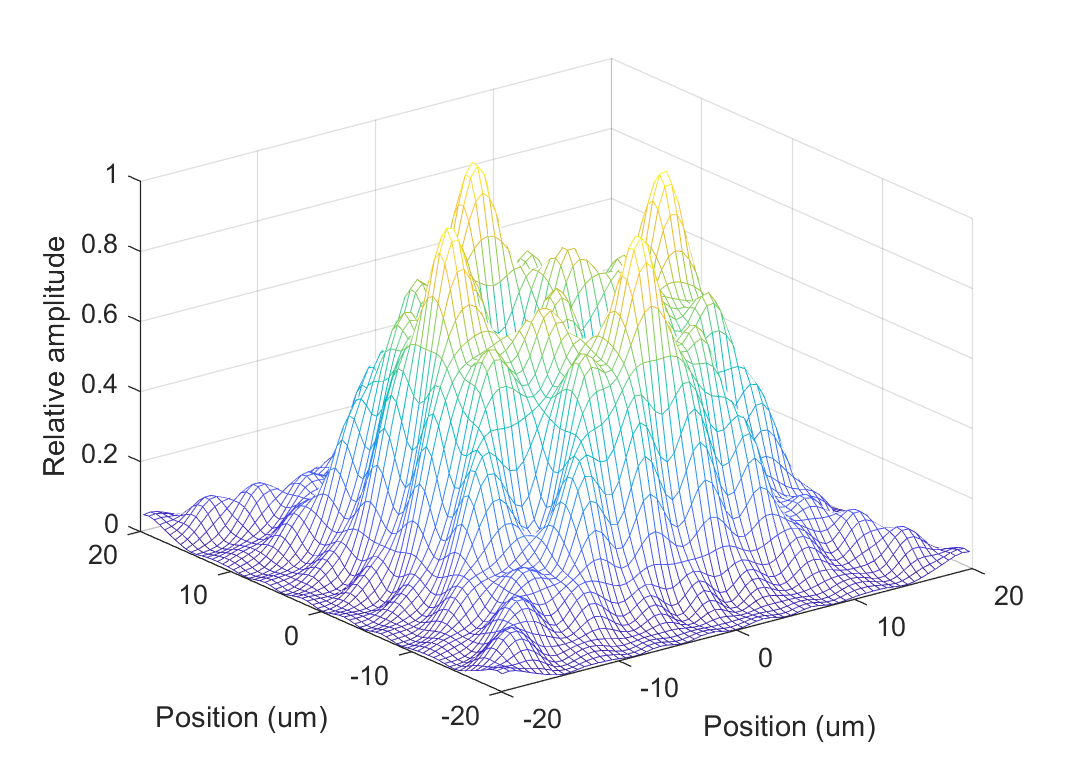

wvfPlot(wvf3, '2d psf space normalized','um',wList,maxUM);

## Examine effect of the j = 5 (6th entry), which is called vertical

astigmatism, along the 0 or 90 degree axis. Again we begin with the wvf0, which has a vector of zero zcoeffs in it by default.

We can see that unlike the 3rd coefficient, this coefficient for astigmatism is aligned to the x and y axes.

vertical_astig = 2;                         
wvf5 = wvfSet(wvf0,'zcoeffs',vertical_astig,{'vertical_astigmatism'});
wvf5 = wvfComputePSF(wvf5);
wvfPlot(wvf5,'2d pupil phase space','mm',wList,maxMM);
wvfPlot(wvf5,'2d psf space normalized','um',wList,maxUM);

## Make plots of various pupil functions

And their respective point-spread functions for different Zernike polynomials of 1st through 3rd radial orders (OSA j indices 1 through 9).

Each time through the loop we see the effect of wiggling one coefficient.

In this loop, we plot the wavefront aberrations (measured in microns), in addition to the pupil function phase (radians), and the PSF.

The wavefront aberration plots we get match those  [http://www.traceytechnologies.com/resources_wf101.htm](http://www.traceytechnologies.com/resources_wf101.htm) except for the fact that their green is postive and our red is positive. Note that there is considerable disagreement about the Zernikes in the pictures on the web. See comment in v_wvfZernikePolynomials for a more expansive discussion.

wvf0 = wvfCreate;

Pupil diameter in mm.  This will change to meters some day


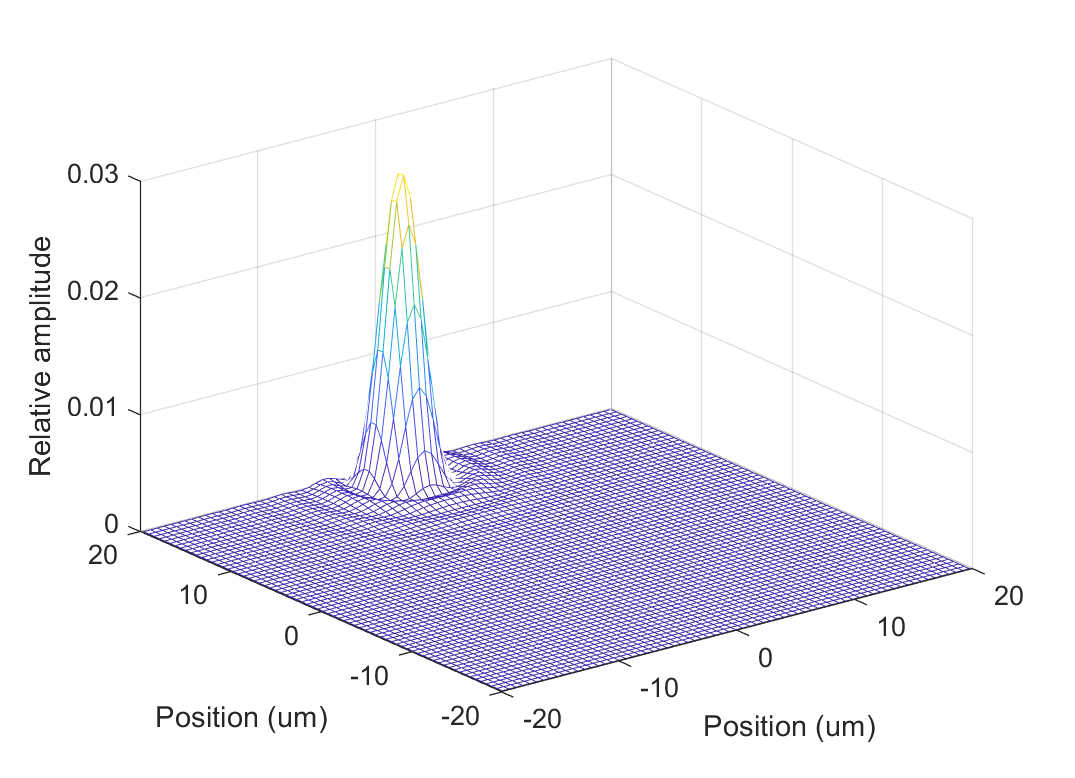

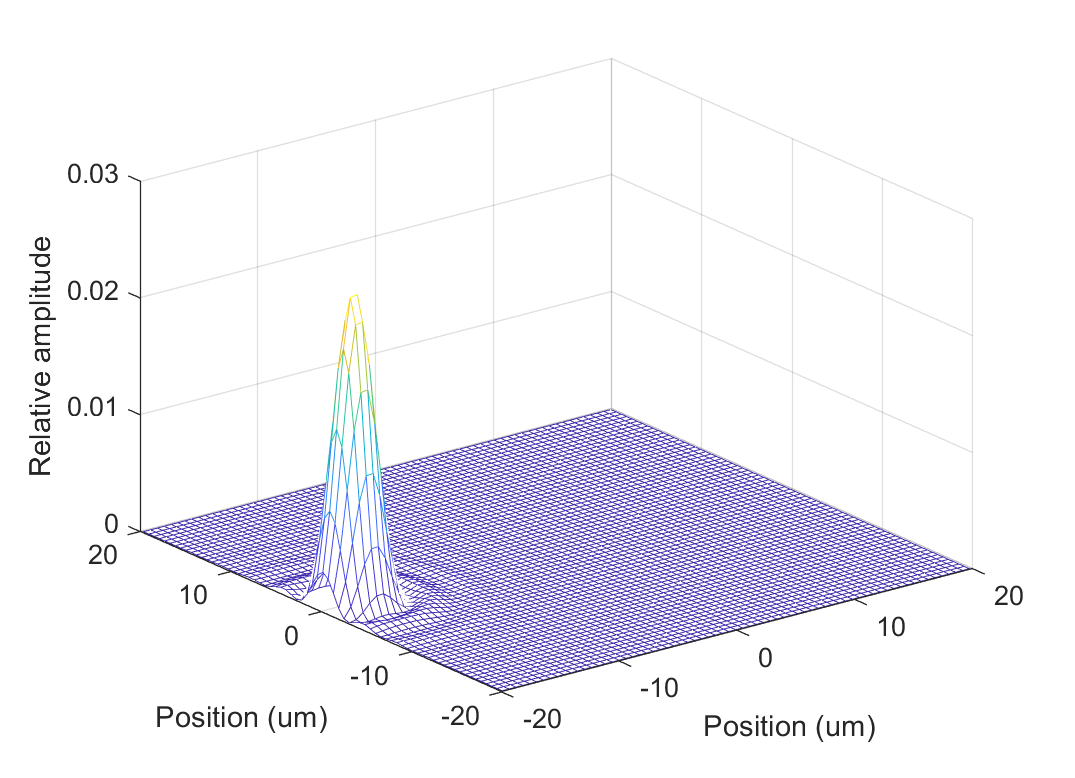

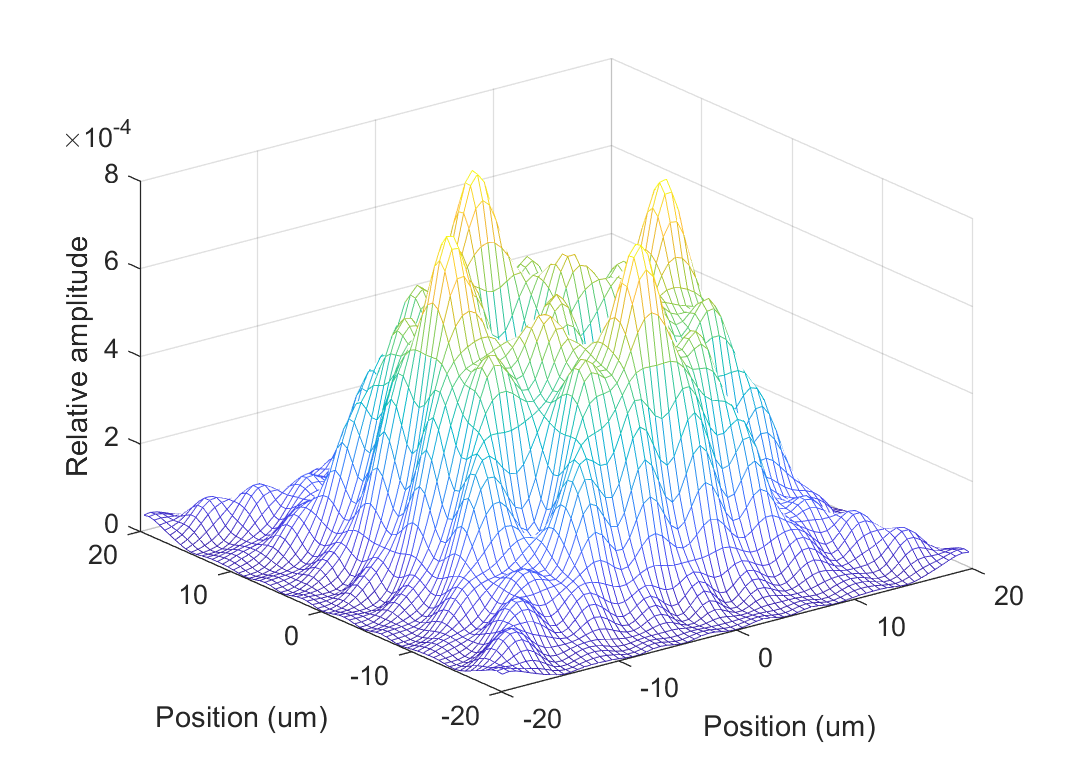

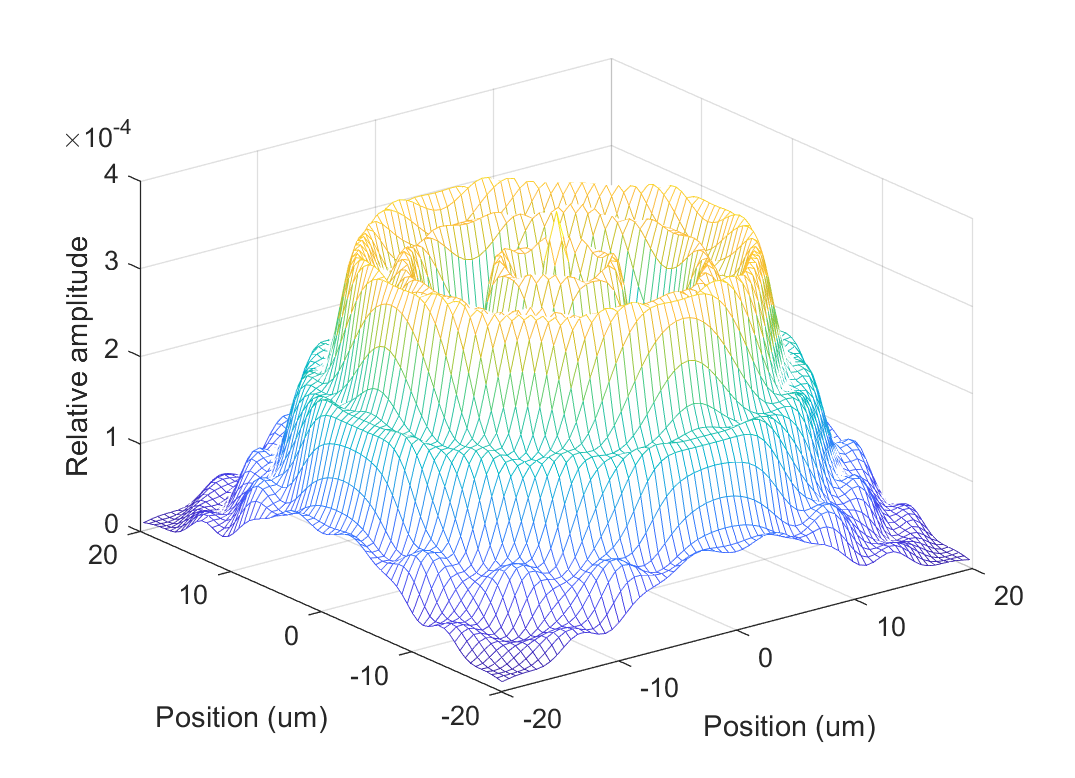

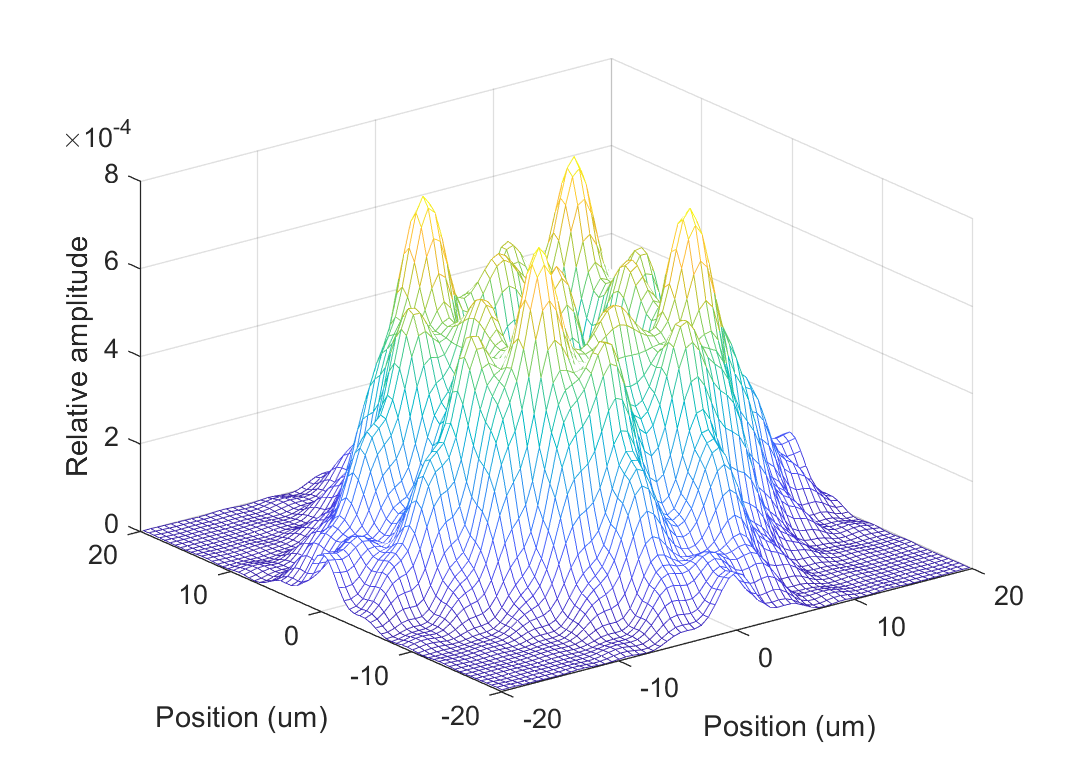

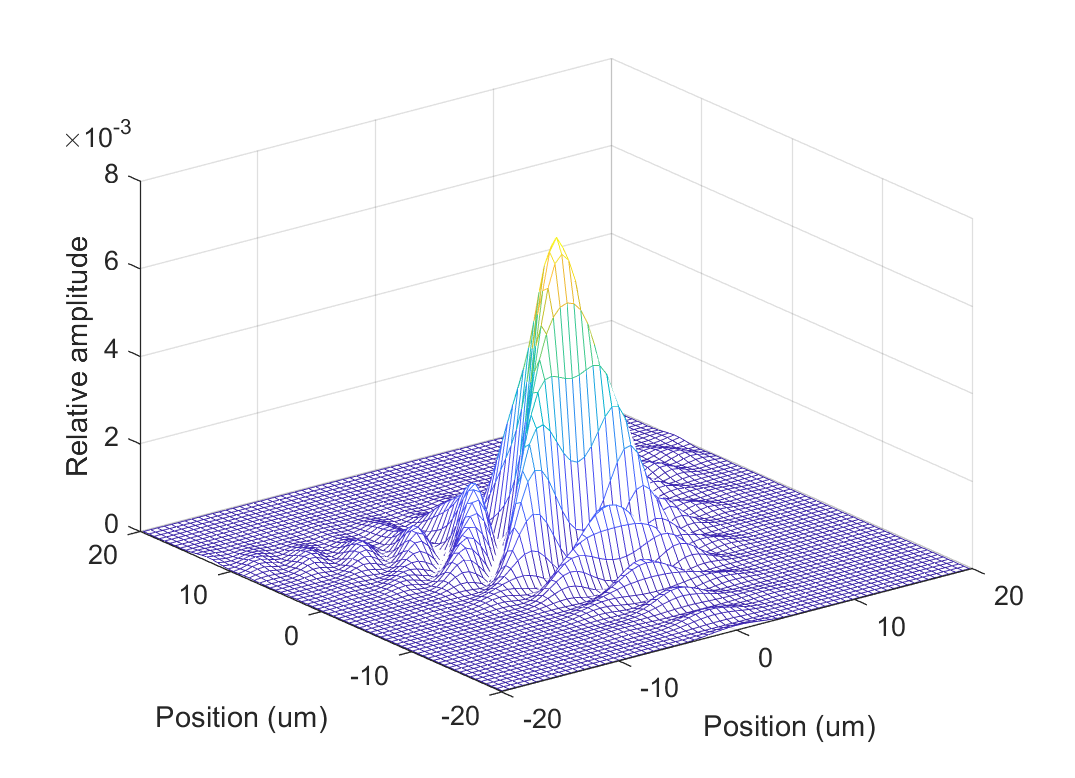

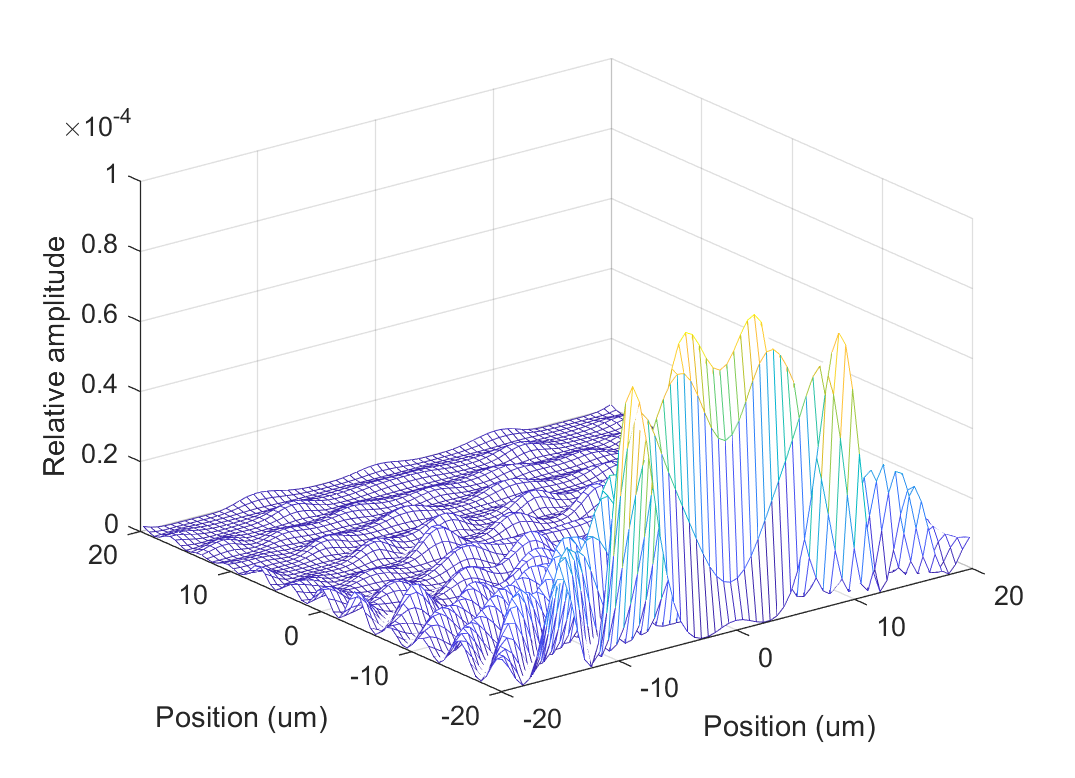

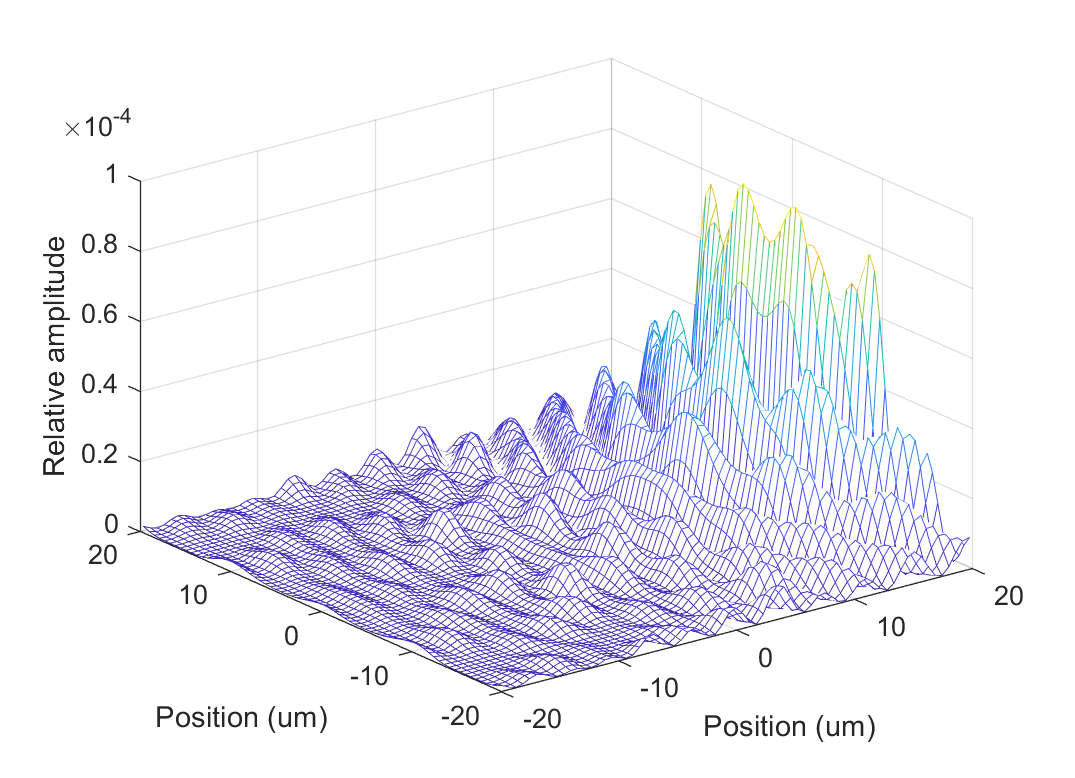


% pupilfuncrangeMM = 4;
jindices = 1:9;
maxUM = 20; 
for ii = jindices
    vcNewGraphWin;
    insertCoeff = 2;
    wvf = wvfSet(wvf0,'zcoeffs',insertCoeff,ii);
    wvf = wvfComputePSF(wvf);
    [n,m] = wvfOSAIndexToZernikeNM(ii);
    wvfPlot(wvf,'2d psf space','um',wList,maxUM,'no window');
end

## How longitudinal chromatic aberration (LCA) affects the PSF / "Defocus"

What happens if we want to know how the PSF looks for different wavelengths? You may have learned that optical systems can have chromatic aberration, where one wavelength is brought into focus but others may be blurry because they are refracted closer or farther from the imaging plane. In this case, the PSF is dependent on wavelength.

We can set this using the  "in-focus wavelength" of our wvf. This code indicates that the data is given for a nominal focus of 550 nm, which is also the default in wvfCreate. We also now explictly set the wavelength for which the PSF is calculated to 550 nm (this is also the default.

wvf0 = wvfCreate;

Pupil diameter in mm.  This will change to meters some day


wvf0 = wvfSet(wvf0,'wave',550); 

It turns out that all aberrations other than "Defocus" are known to vary only slightly with wavelength. As a result, the Zernike coefficients don't have to be modified, apart from one. This is the j = 0 "defocus" coefficient. It is what typical eyeglasses correct for using + or - diopters lenses. The wavefront toolbox combines the longitudinal chromatic aberration (LCA) into this coefficient when it calculates the pupil function.  The LCA itself is computed based on the difference between the measurement wavelength (for which the defocus coefficient is specified) and the wavelength being calclated for.

wvf0 = wvfComputePSF(wvf0);
wList = wvfGet(wvf0,'wavelengths');
vcNewGraphWin;
maxMM = 3; 
wvfPlot(wvf0,'1dpsfspacenormalized','mm',wList,maxMM,'no window');
hold on;


#### Change the calculated wavelength to 600.

The new psf is wider due to the longitudinal chromatic aberration, even though it's still just the diffraction-limited wavefront function (the Zernike coefficients are still 0).

theWavelength = 600;
wvf1 = wvfCreate;

Pupil diameter in mm.  This will change to meters some day


wvf1 = wvfSet(wvf1,'wavelengths',theWavelength);
wList = wvfGet(wvf1,'wavelengths');
wvf1 = wvfComputePSF(wvf1);
wvfPlot(wvf1,'1dpsf space normalized','mm',wList,maxMM,'no window');


To unpack this, we can do explicitly what is done inside the pupil function calculation.  First we LCA from the wavelength difference, then act as if the measured wavelength (where there is no LCA) is the calculated wavelength.  We do this by changing the measured wavelength specification.  Finally, we add in the LCA to the defocus coefficient.

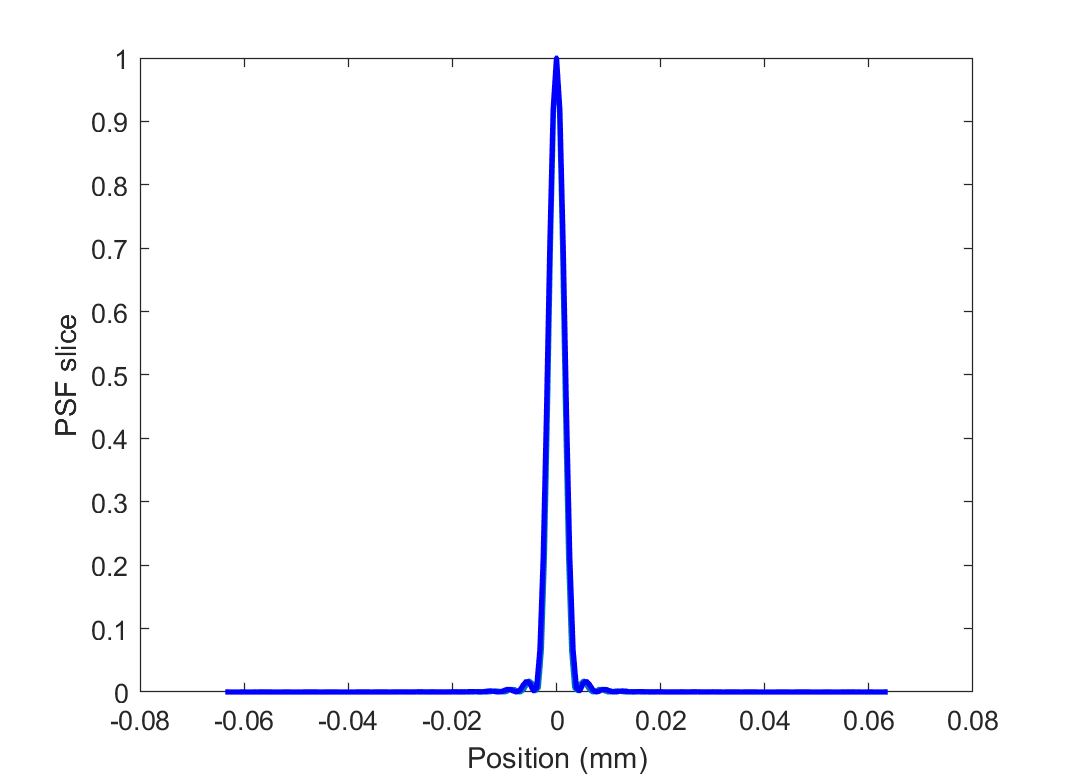

wvf2 = wvf1;
lcaDiopters = wvfLCAFromWavelengthDifference(wvfGet(wvf2,'wavelength','nm'),wvfGet(wvf2,'wavelengths','nm'));
lcaMicrons = wvfDefocusDioptersToMicrons(-lcaDiopters,wvfGet(wvf2,'pupil size'));
wvf2 = wvfSet(wvf2,' wavelength',wvfGet(wvf2,' wavelengths','nm'));
wList = wvfGet(wvf2,' wavelengths');
defocus = wvfGet(wvf2,'zcoeffs',{'defocus'});
defocus = defocus + lcaMicrons;
wvf2 = wvfSet(wvf2,'zcoeffs',lcaMicrons,{'defocus'});
wvf2 = wvfComputePSF(wvf2);
[udataS, pData] = wvfPlot(wvf2,'1dpsf space normalized','mm',wList,maxMM,'no window');
set(pData,'color','b','linewidth',2);